# ECG Signal Denoising Using Wavelet Transform and Particle Swarm Optimization

## INTRODUCTION

- Electrocardiogram (ECG) is an important signal used to monitor the heart and detect cardiovascular diseases.

- ECG signals are non-stationary

- An ECG signal is called non-stationary when the statistical properties change over the time.

- The mean, variance, frequency content, or amplitude of the ECG signal do not remain constant,they vary with the time.

- ECG signal is often corrupted by noise like white Gaussian noise (WGN),power line interference (PLI).

- We are using Wavelet Transform (WT) for ECG signal denoising.

- To improve the denoising performance, we are using Particle Swarm Optimization (PSO).

## PROBLEM STATMENT

- ECG signals are often corrupted by noise therefore it is necessary to denoise the signal while preserving the important information.

## OBJECTIVE

- To Denoise the ECG signals using Wavelet Transform

- To use Particle Swarm Optimization (PSO) to find the optimal parameters of the Wavelet Transform.

## WAVELET IS DEFINED AS


$$\[
C(a,b) = \sum_{n \in Z} x(n)\, g_{j,k}(n)
\]

\[
g_{j,k}(n) = 2^{j/2}\, g(2^{j}n - k)
\]

\[
a = 2^{-j}
\]

\[
b = k2^{-j}
\]$$


- $x(n)$ is the Original Signal

- $ g_{j,k}(n)$ is the Mother Wavelet

- a is scaling, b is shifting 

## DISCRETE WAVELET TRANSFORM

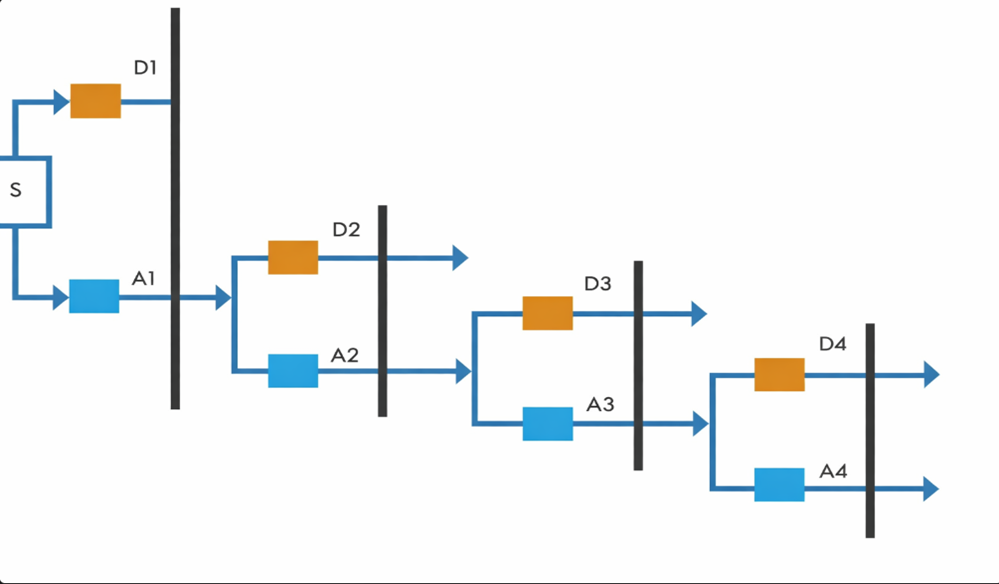

## ECG Signal Decomposition:

- In Wavelet Decomposition, approximation coefficients contain the low-frequency information of the signal, whereas detail coefficients contain the high-frequency information.


$$\[
cA_i(t) = \sum_{k=-\infty}^{\infty} cA_{i-1}(K)\,\phi_i(t-K)
\]

\[
cD_i(t) = \sum_{k=-\infty}^{\infty} cD_{i-1}(K)\,\psi_i(t-K)
\]$$
  

- $cA_i(t)$: Approximation coefficients at decomposition level i

- $cA_{i-1}{K}$: Approximation coefficients from the previous level

- $\phi_i(t)$: Wavelet function at level i

- K: summation index

- $cD_i(t)$:Detail coefficients at decomposition level i

- $cD_{i-1}{K}$: Detail coefficients from the previous level

- $\psi_i(t)$: scaling function at level i

- K: summation index

## Thresholding:


$$\[
\delta =
\begin{cases}
\sigma (0.3936 + 0.1829 \log_{2} N), & N > 32 \\
0, & N \leq 32
\end{cases}
\]$$



$$\[
\sigma = \frac{\mathrm{median}(|D_{ij}|)}{0.6745}
\]$$


- N is the length of the signal vector.

- i→ decomposition level

- j → index of the coefficient

- $\sigma$ is  noise standard deviation

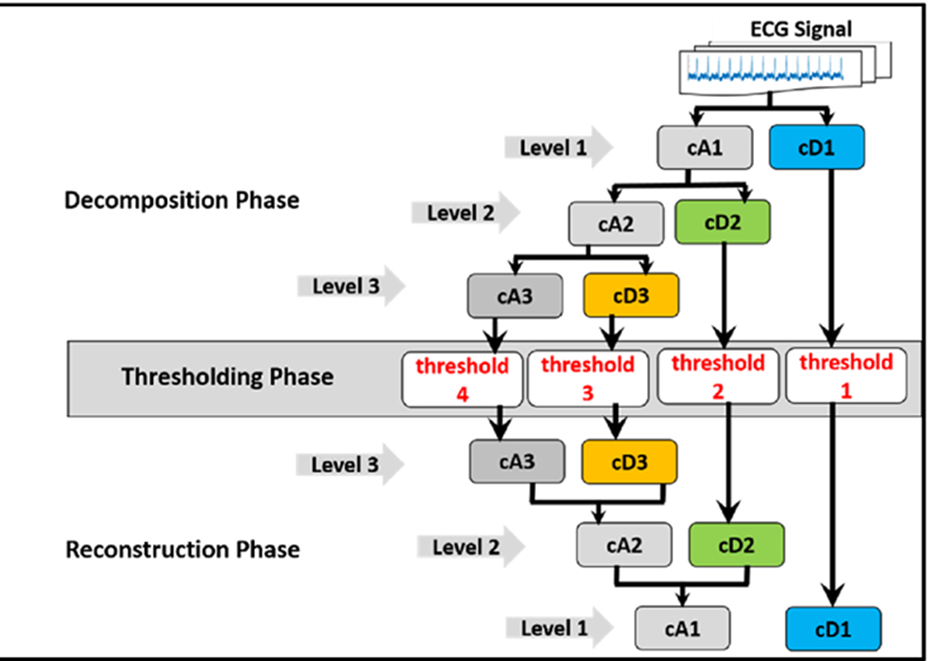

## Thresholding Function

#### Soft Thresholding

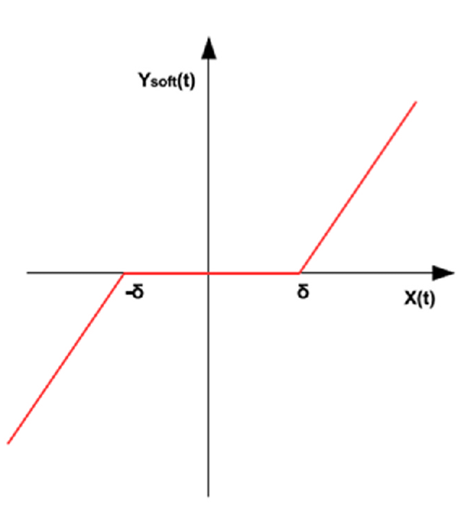 


$$\[
y_{\text{soft}}(x) =
\begin{cases}
\text{sign}(x)(|x|-\delta), & |x| > \delta \\
0, & |x| \le \delta
\end{cases}
\]$$


#### Hard Thresholding

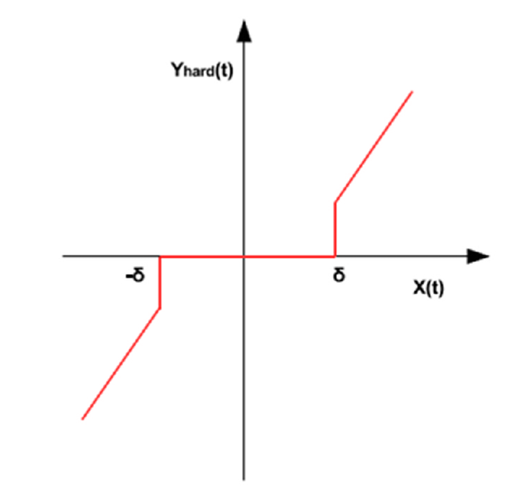


$$\[
y_{\text{hard}}(x) =
\begin{cases}
x, & |x| > \delta \\
0, & |x| \le \delta
\end{cases}
\]$$


## Reconstruction


$$\[
ECG_{\text{denoised}} =
\sum_{k=-\infty}^{\infty} cA_L(K)\,\phi_i(t-K)
+
\sum_{l=1}^{L} \sum_{k=-\infty}^{\infty} cD_{i+1}(K)\,\psi_i(t-K)
\]$$


- $cA_L(K)$ -  Approximation coefficients at final level L

- $cD_i(K)$ - Thresholded detail coefficients at level i

- $\phi(t)$ - Scaling (low-pass) function

- $\psi_i(t)
$ - Wavelet (high-pass) function

- L - Total number of decomposition levels

## Particle Swarm Optimisation

Why we are doing PSO?

In MATLAB, we use the built-in function **wden** to perform wavelet denoising. This function requires five parameters: the wavelet basis function (Φ), decomposition level (L), threshold function (β), threshold selection rule (λ), and rescaling method (ρ). The quality of ECG denoising depends heavily on selecting the correct combination of these parameters. Instead of choosing them manually, we use Particle Swarm Optimization (PSO) to automatically search the parameter.So PSO mainly optimizes the Level(L)

- PSO is an optimization algorithm used to find the best solution to a problem.

- It is inspired by the behavior of birds or fish moving in groups.

- When they search for food, they do not know the exact location.

- But one bird may find food first.

- The other birds observe its movement and move toward that area.

- In PSO, many possible solutions are created and called particles.

- A group of these particles is called a swarm.

- Particle → one possible solution

- Swarm → group of particles

- Particle x=[$\phi,\beta,L,\lambda,\rho$]

- In Each particle we have 5 parameters such as

- Wavelet basis function (ϕ) - Coiflet , Symlet , Daubechies, Fejer-Korovkin and Biorthogonal 

- Threshold function (β) – soft ,hard

- Level of decomposition (L) – 1 to 10 

- Threshold selection rule (λ) - Sqtwolog, Minimax, Heursure, and Rigsure

- rescaling approach (ρ) - No scaling (one), one level (sln), Several levels (mln). 

## Threshold Selection Rules

#### sqtwolog 

uses a formula : $\[
T = \sigma \sqrt{2 \log M}
\]$ , here M=No.of Coefficients,$\sigma$= noise standard deviation

#### Minimax

uses a formula : $\[
\delta =
\begin{cases}
\sigma (0.3936 + 0.1829 \log_{2} N), & N > 32 \\
0, & N \leq 32
\end{cases}
\]$        $\[
\sigma = \frac{\mathrm{median}(|D_{ij}|)}{0.6745}
\]$  ,

- N is the length of the signal vector.

- i→ decomposition level

- j → index of the coefficient

- $\sigma$ is  noise standard deviation

#### Rigrsure

- Estimates the error between denoised and true signal

- Chooses threshold that minimizes this error.

#### **Heursure**

- Rigrsure + Sqtwolog.

- If noise is small → use Rigrsure

- If noise is large → use Sqtwolog

## Velocity


$$\[
v_i(t+1) = w\,v_{i,j}(t) + c_1 r_{1,j}(t)\big(y_{i,j}(t) - x_{i,j}(t)\big) + c_2 r_{2,j}(t)\big(\hat{y}_j(t) - x_{i,j}(t)\big)
\]$$



$$\[
(y_{i,j}(t) - x_{i,j}(t)) \rightarrow \text{Local Best}
\]

\[
(\hat{y}_j(t) - x_{i,j}(t)) \rightarrow \text{Global Best}
\]$$


- c1 and c2 are two acceleration constants

- w is inertia weight

- r1 and r2 generate a uniformly distributed random number between 0 and 1

## Position


$$\[
x_i(t+1) = x_i(t) + v_i(t+1)
\]$$


## Fitness Function 


$$\[
SNR_{imp} = SNR_{output} - SNR_{input}
\]

\[
SNR_{input} = 10 \log_{10} \frac{\sum_{n=1}^{N} [S(n)]^2}{\sum_{n=1}^{N} [S(n) - \tilde{S}(n)]^2}
\]

\[
SNR_{output} = 10 \log_{10} \frac{\sum_{n=1}^{N} [S(n)]^2}{\sum_{n=1}^{N} [S(n) - \hat{S}(n)]^2}
\]$$


- S(n) is the Signal

- $\tilde{S}(n)$ is the noisy ECG signal

- $\hat{S}(n)$ is the denoised ECG signal

## Toy Example for PSO

- Initializing all possible Mother Wavelets and giving the index

- Initializing all possible Threshold rules and giving the index

- Initializing all possible Threshold and giving the index

- Initializing all possible Rescaling and giving the index

- Assume we have 3 particles and ramdomly generated some index numbers for each parameter

- we Initially take all the velocity as zero

- and calculated the SNR_improvement (Fitness Function)

- Among all the three particles we get high fitness on particle 2 So is (gbest=P2) 

- Because of High Fitness among all the 3 particles

#### Velocity =w*velocity+C1*r1*(pbest– particle)+C2*r2*(gbest- particle)

#### New Velocity is 2.4

### Position Update

Particle.L=round(L+velocity)

L=4+2.4=6.4

L=6

### Iteration-2

previous velocity = 2.4

New Velocity= 1.68

## Position Update

## Random Reset Parameters

### Particle After Iteration-2

Converted

### Fitness (Iteration-2)

### Final Evolution Table

# ECG Signal Denoising using Wavelet Tranform 

#### Loading Dataset

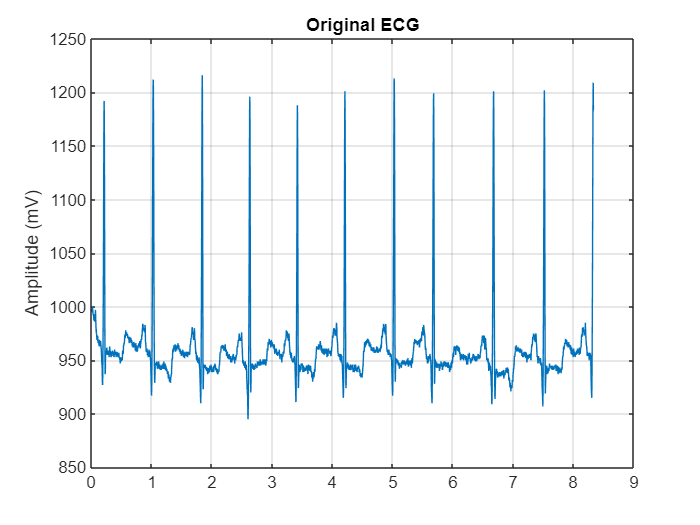

clc;
clear;
close all;

data = readmatrix('100.csv');
x = data(:,2);
x = x(:);
N = length(x);

fs = 360;
t = (0:N-1)/fs;

figure;
plot(t(1:3000), x(1:3000))
title('Original ECG')
ylabel('Amplitude (mV)')
grid on

#### Adding WGN(White Gaussian Noise)

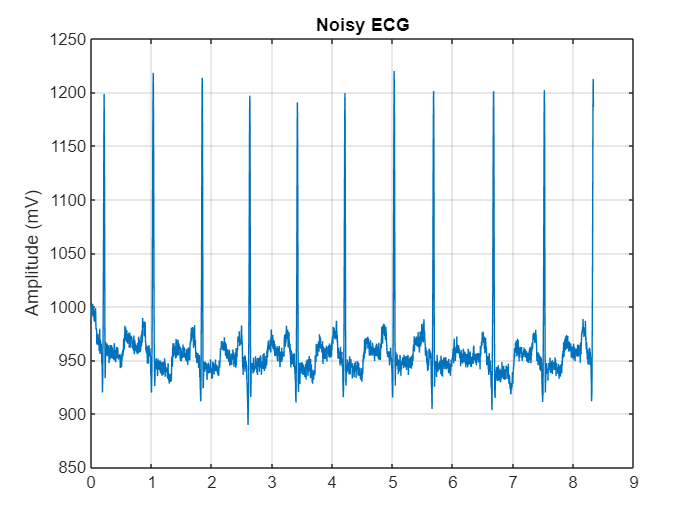

x_mean = mean(x);
noise = 0.1 * std(x) * randn(size(x));
x_noisy = (x - x_mean) + noise;

figure;
plot(t(1:3000), x_noisy(1:3000) + x_mean)
title('Noisy ECG')
ylabel('Amplitude (mV)')
grid on

#### Decomposition

phi = [0.5 1 0.5];
psi = [1 0 -1];
phi = phi / norm(phi);
psi = psi / norm(psi);
L = length(phi);

# Orthogonality Demonstration

%% Orthogonality Demonstration
dot_product = sum(phi .* psi);

fprintf('\nInner product between phi and psi = %.6f\n', dot_product);


Inner product between phi and psi = 0.000000



if abs(dot_product) < 1e-6
    disp('phi and psi are ORTHOGONAL');
else
    disp('phi and psi are NOT orthogonal');
end

phi and psi are ORTHOGONAL



% Check orthonormal condition
norm_phi = sum(phi.^2)

norm_phi = 1.0000

norm_psi = sum(psi.^2)

norm_psi = 1.0000

levels = 3;
x_level = x_noisy;

cA = cell(levels,1);
cD = cell(levels,1);

for i = 1:levels
    len = length(x_level);
    tempA = zeros(len,1);
    tempD = zeros(len,1);

    for k = 1:len
        for n = 1:L
            idx = k + n - 1;
            if idx <= len
                tempA(k) = tempA(k) + x_level(idx)*phi(n);
                tempD(k) = tempD(k) + x_level(idx)*psi(n);
            end
        end
    end

    cA{i} = tempA(1:2:end);
    cD{i} = tempD(1:2:end);
    x_level = cA{i};
end

#### Thresholding

for i = 1:levels
    sigma = median(abs(cD{i})) / 0.6745;
    lambda = sigma * sqrt(2*log(length(cD{i})));
    cD{i} = sign(cD{i}) .* max(abs(cD{i}) - lambda, 0);
end

#### Reconstruction

for i = levels:-1:1
    len = length(cA{i});
    x_rec = zeros(len*2,1);

    for k = 1:len
        for n = 1:L
            idx = 2*k + n - 2;
            if idx <= length(x_rec)
                x_rec(idx) = x_rec(idx) + cA{i}(k)*phi(n) + cD{i}(k)*psi(n);
            end
        end
    end

    cA{i} = x_rec;
end

x_denoised = x_rec(1:N);% + x_mean;

x_norm = x_denoised / max(abs(x_denoised));


Corealation Demonstration

for i = 1:levels
    len = min(length(cA{i}), length(cD{i}));
    corr_val = corr(cA{i}(1:len), cD{i}(1:len));
    
    fprintf('Correlation at level %d = %.6f\n', i, corr_val);
end

Correlation at level 1 = 0.000648
Correlation at level 2 = 0.000975
Correlation at level 3 = 0.001329


#### Plotting

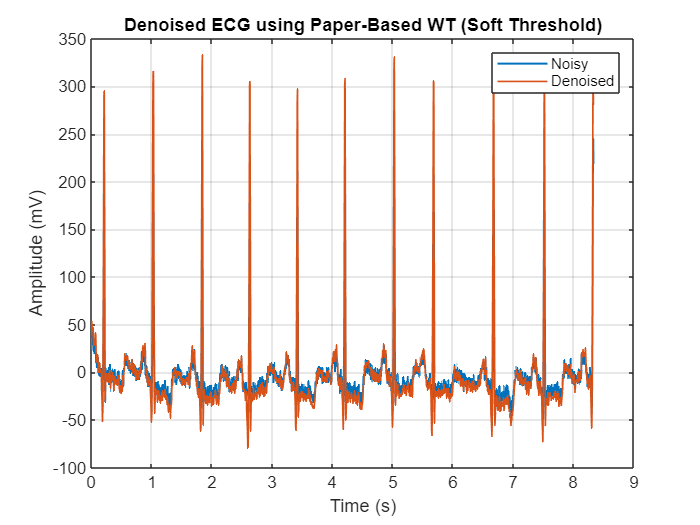

figure;
plot(t(1:3000), x_noisy(1:3000),LineWidth=1.2);hold on
plot(t(1:3000), x_denoised(1:3000),LineWidth=1);hold off
legend("Noisy","Denoised")
title('Denoised ECG using Paper-Based WT (Soft Threshold)')
xlabel('Time (s)')
ylabel('Amplitude (mV)')
grid on

# Function to plot the wavelet basis function (phi,psi shifting and scaling)

function ssx = scsh(j, k, x)

    % Scaling
    a = 2^j;
    x_scaled = sqrt(a) * x;

    % Shifting
    n = length(x_scaled);
    ssx = zeros(1, n + k);

gjk =     0.7071         0   -0.7071


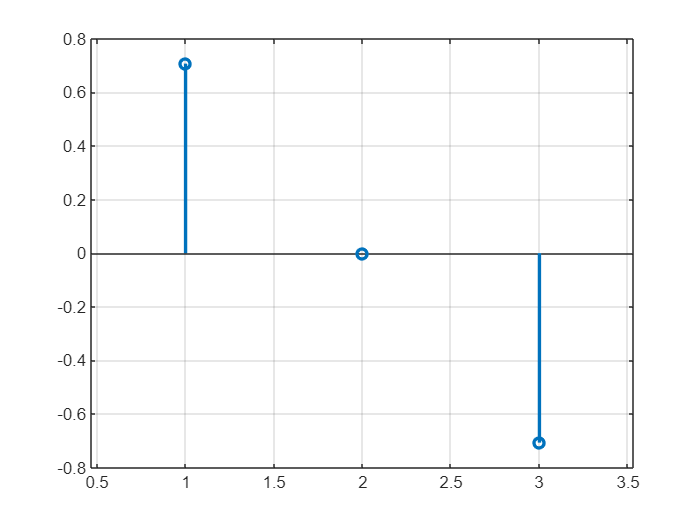

    ssx(k+1 : k+n) = x_scaled;


end


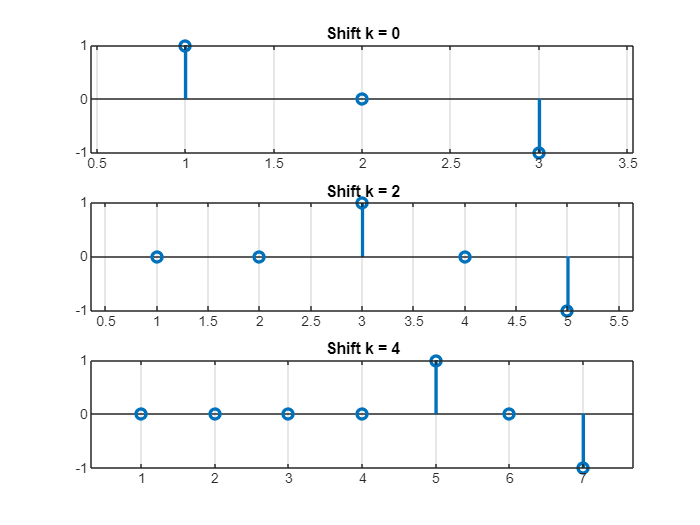

clc; clear; close all;

g = [1 0 -1];
g = g / norm(g);

j = 1;                      % fixed scale
k_vals = [0 2 4];         % different shifts

gjk = scsh(0,0,g)
stem(gjk,'LineWidth',2)

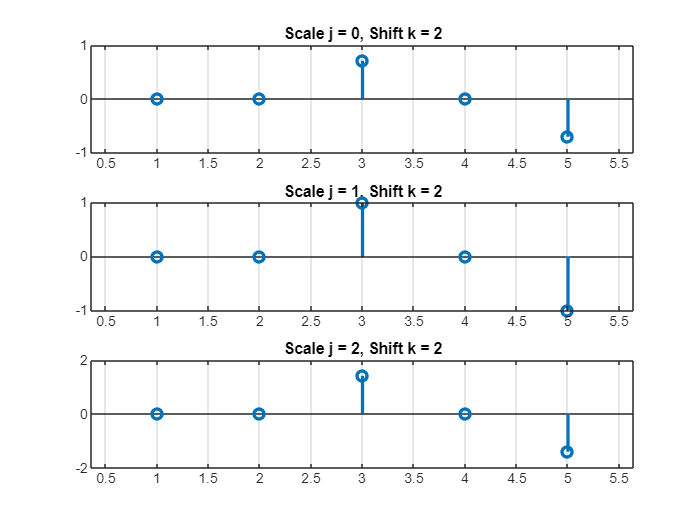

grid on

figure;
for i = 1:length(k_vals)

    g_jk = scsh(j, k_vals(i), g);

    subplot(length(k_vals),1,i)
    stem(g_jk, 'LineWidth', 2)
    title(['Shift k = ', num2str(k_vals(i))])
    grid on

end

clc; clear; close all;

g = [1 0 -1];
g = g / norm(g);

k = 2;                 % fixed shift
j_vals = [0 1 2];      % different scales


figure;

for i = 1:length(j_vals)

    g_jk = scsh(j_vals(i), k, g);

    subplot(length(j_vals),1,i)
    stem(g_jk, 'LineWidth', 2)
    title(['Scale j = ', num2str(j_vals(i)), ', Shift k = ', num2str(k)])
    grid on

end

# Checking How much Noise level can be removed and clean signal can be reconstructed

clc;
clear;
close all;
tic

data = readmatrix('100.csv');
x = data(:,2);
x = x(:);
N = length(x);

fs = 360;
t = (0:N-1)/fs;


figure;
plot(t(1:3000), x(1:3000))
title('Original ECG')
ylabel('Amplitude (mV)')
grid on

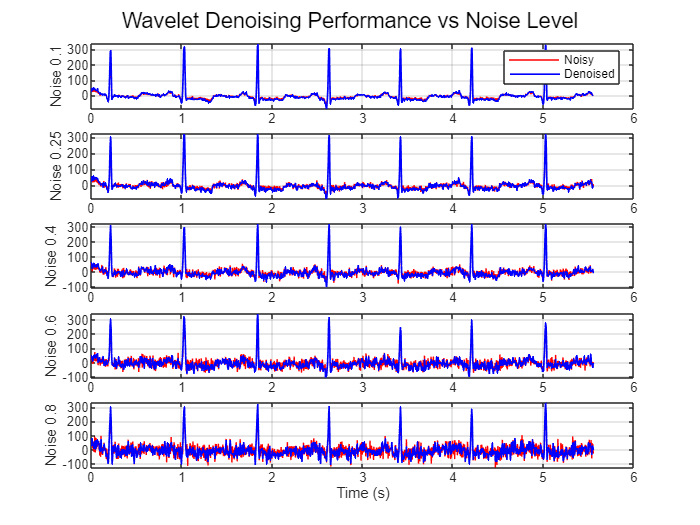

Elapsed time is 2.862574 seconds.



x_mean = mean(x);

%% Wavelet Filters 
phi = [0.5 1 0.5];
psi = [1 0 -1];
phi = phi / norm(phi);
psi = psi / norm(psi);
L = length(phi);

levels = 3;   

%% Noise Study
noise_levels = [0.1 0.25 0.4 0.6 0.8];

figure;
sgtitle('Wavelet Denoising Performance vs Noise Level')

for j = 1:length(noise_levels)

    %% Add Noise
    K = noise_levels(j);
    noise = K * std(x) * randn(size(x));
    x_noisy = (x - x_mean) + noise;

    %% Decomposition
    x_level = x_noisy;
    cA = cell(levels,1);
    cD = cell(levels,1);

    for i = 1:levels
        len = length(x_level);
        tempA = zeros(len,1);
        tempD = zeros(len,1);

        for k = 1:len
            for n = 1:L
                idx = k + n - 1;
                if idx <= len
                    tempA(k) = tempA(k) + x_level(idx)*phi(n);
                    tempD(k) = tempD(k) + x_level(idx)*psi(n);
                end
            end
        end

        cA{i} = tempA(1:2:end);
        cD{i} = tempD(1:2:end);
        x_level = cA{i};
    end

    %% Soft Thresholding
    for i = 1:levels
        sigma = median(abs(cD{i})) / 0.6745;
        lambda = sigma * sqrt(2*log(length(cD{i})));
        cD{i} = sign(cD{i}) .* max(abs(cD{i}) - lambda, 0);
    end

    %% Reconstruction
    for i = levels:-1:1
        len = length(cA{i});
        x_rec = zeros(len*2,1);

        for k = 1:len
            for n = 1:L
                idx = 2*k + n - 2;
                if idx <= length(x_rec)
                    x_rec(idx) = x_rec(idx) + cA{i}(k)*phi(n) + cD{i}(k)*psi(n);
                end
            end
        end

        cA{i} = x_rec;
    end

    x_denoised = x_rec(1:N);

    %% Plot Results
    subplot(length(noise_levels),1,j)
    plot(t(1:2000), x_noisy(1:2000),'r'); hold on
    plot(t(1:2000), x_denoised(1:2000),'b','LineWidth',1)
    ylabel(['Noise ', num2str(K)])
    grid on
    if j == 1
        legend('Noisy','Denoised')
    end

end

xlabel('Time (s)')
toc

# PSO main Function

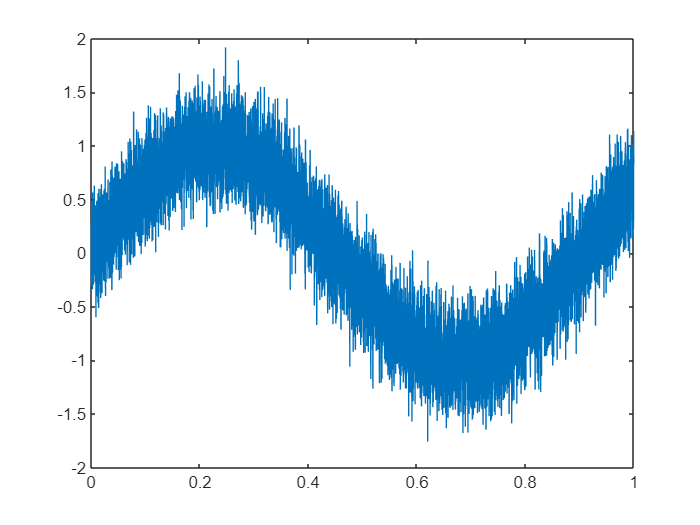

function [S_hat_final, SNR_input, SNR_output, MSE, RMSE, PRD] = pso_wt_denoise(S, N_noisy)

N = length(S);
fs = 360;
t = (0:N-1)/fs;

%% Calculate SNR input
SNR_input = 10*log10(sum(S.^2) / sum((S - N_noisy).^2));

%% Wavelet parameters


Iteration 1 Best SNR improvement = 25.5648
Iteration 2 Best SNR improvement = 25.5648


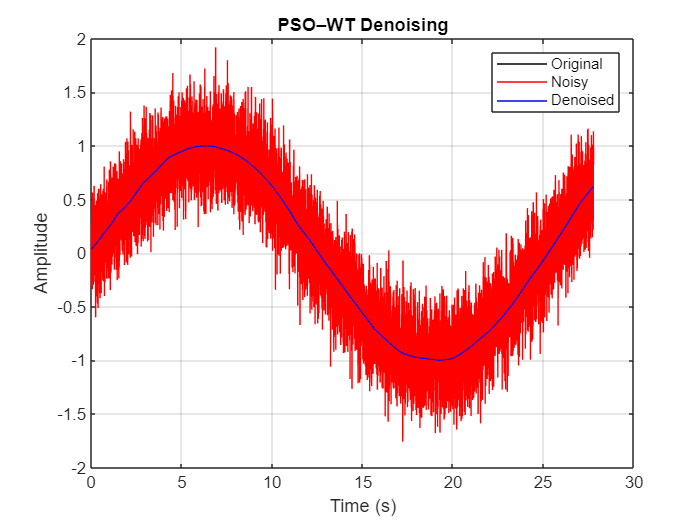

Phi_list = {'coif1','coif3','sym3','sym5','db4','db6'};
beta_list = {'s','h'};

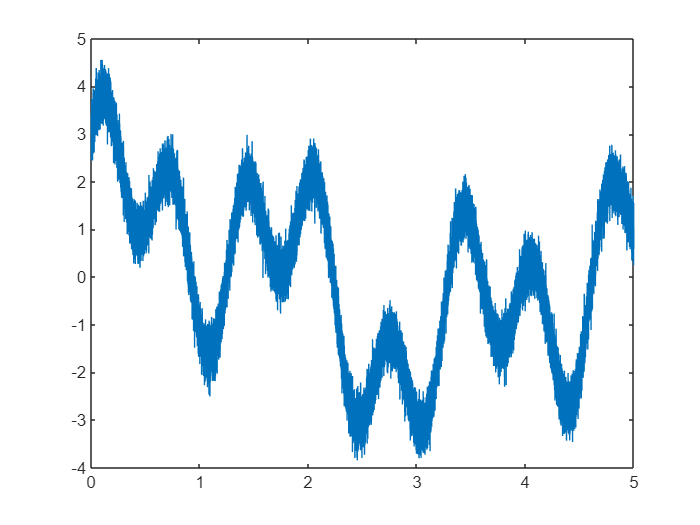

lambda_list = {'rigrsure','sqtwolog','heursure','minimaxi'};
rho_list = {'one','sln','mln'};

L_min = 1;
L_max = 10;

%% PSO parameters


Iteration 1 Best SNR improvement = 26.2238
Iteration 2 Best SNR improvement = 26.4022


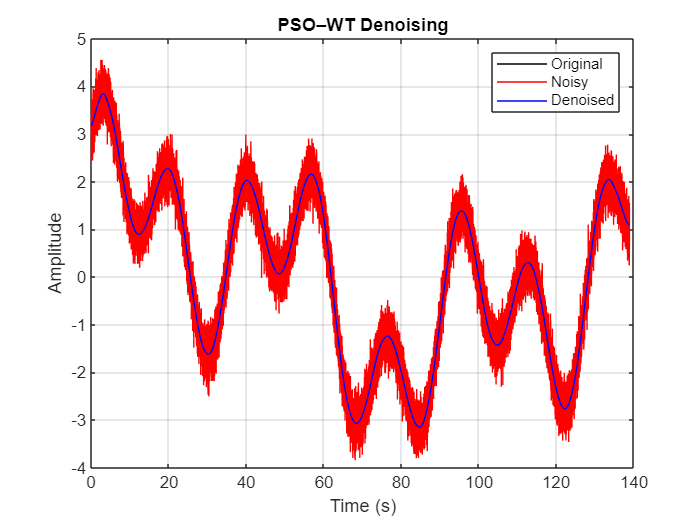

C1 = 2;
C2 = 2;

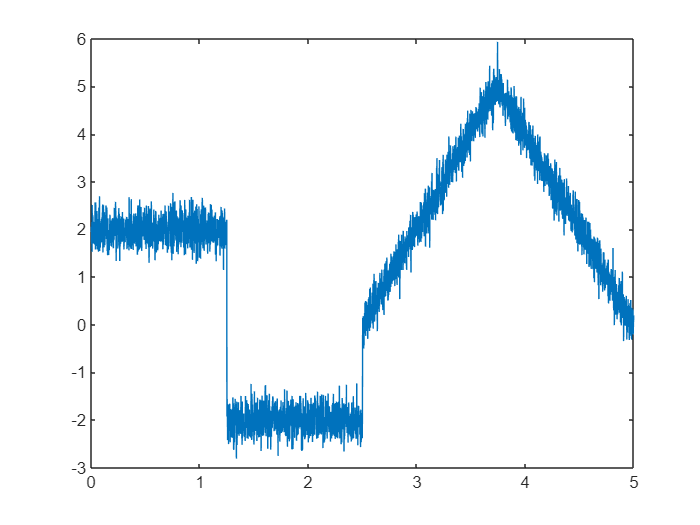

itermax = 2;
pop_size = 50;
w = 0.7;

%% Initialise swarm

for i = 1:pop_size
    
    particle(i).Phi = randi(length(Phi_list));
    particle(i).L = randi([L_min L_max]);
    particle(i).beta = randi(2);

Iteration 1 Best SNR improvement = 14.3531
Iteration 2 Best SNR improvement = 14.7963


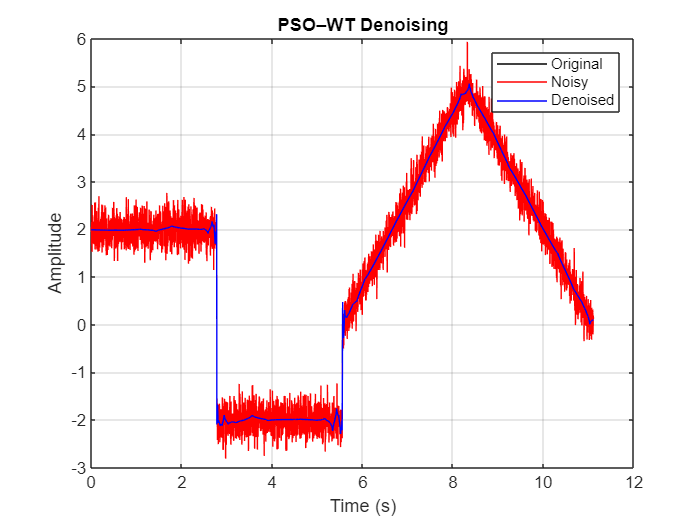

    particle(i).lambda = randi(length(lambda_list));
    particle(i).rho = randi(length(rho_list));

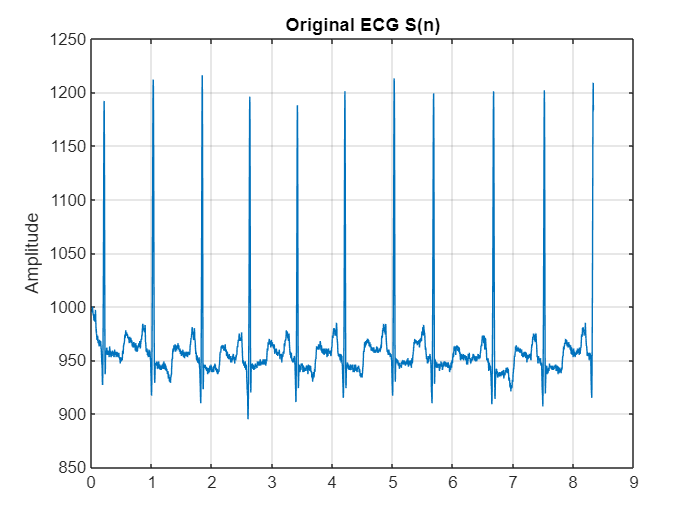

    
    velocity(i).L = 0;
end

%% Initial fitness evaluation

for i = 1:pop_size
    
    Phi = Phi_list{particle(i).Phi};
    L = particle(i).L;
    beta = beta_list{particle(i).beta};
    lambda = lambda_list{particle(i).lambda};
    rho = rho_list{particle(i).rho};
    
    S_hat = wden(N_noisy, lambda, beta, rho, L, Phi);
    
    SNR_output = 10*log10(sum(S.^2) / sum((S - S_hat).^2));
    
    fitness(i) = SNR_output - SNR_input;
    
    pbest(i) = particle(i);
    pbest_val(i) = fitness(i);
end

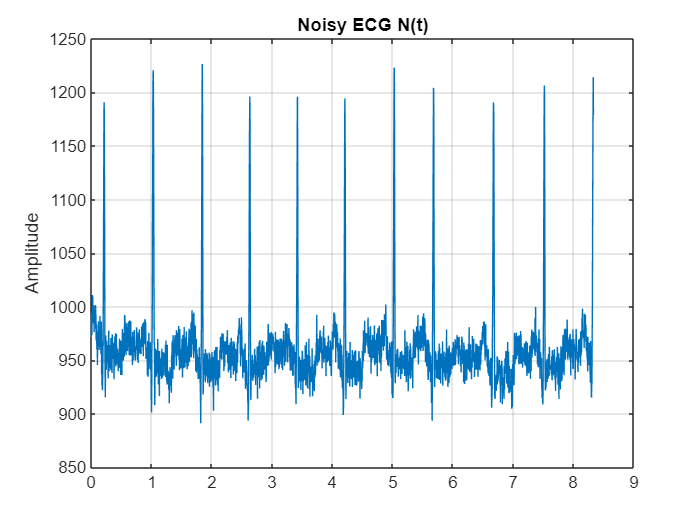


[gbest_val, idx] = max(pbest_val);
gbest = particle(idx);

%% PSO main loop

for iter = 1:itermax
    
    for i = 1:pop_size
        
        r1 = rand;
        r2 = rand;

        
        velocity(i).L = w*velocity(i).L ...
            + C1*r1*(pbest(i).L - particle(i).L) ...

SNR_input = 39.9593

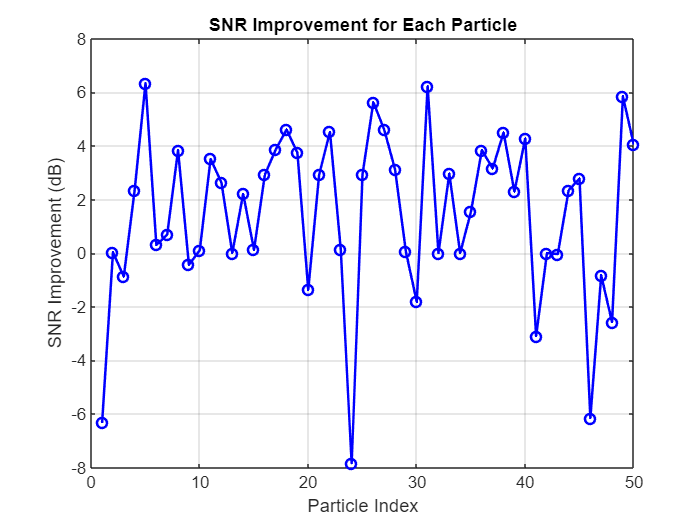

            + C2*r2*(gbest.L - particle(i).L);
        
        particle(i).L = round(particle(i).L + velocity(i).L);
        
        particle(i).L = max(L_min, min(L_max, particle(i).L));
        
        particle(i).Phi = randi(length(Phi_list));
        particle(i).beta = randi(2);
        particle(i).lambda = randi(length(lambda_list));
        particle(i).rho = randi(length(rho_list));
        
        Phi = Phi_list{particle(i).Phi};
        L = particle(i).L;
        beta = beta_list{particle(i).beta};
        lambda = lambda_list{particle(i).lambda};
        rho = rho_list{particle(i).rho};
        
        S_hat = wden(N_noisy, lambda, beta, rho, L, Phi);
        
        SNR_output = 10*log10(sum(S.^2) / sum((S - S_hat).^2));
        
        fitness(i) = SNR_output - SNR_input;
        
        if fitness(i) > pbest_val(i)
            pbest(i) = particle(i);
            pbest_val(i) = fitness(i);
        end
    end
    
    [gbest_val, idx] = max(pbest_val);
    gbest = pbest(idx);
    
    disp(['Iteration ' num2str(iter) ...
        ' Best SNR improvement = ' num2str(gbest_val)]);
end

%% Final denoising

Phi_opt = Phi_list{gbest.Phi};
L_opt = gbest.L;
beta_opt = beta_list{gbest.beta};
lambda_opt = lambda_list{gbest.lambda};
rho_opt = rho_list{gbest.rho};

S_hat_final = wden(N_noisy, lambda_opt, beta_opt, rho_opt, L_opt, Phi_opt);

%% Performance metrics

SNR_output = 10*log10(sum(S.^2) / sum((S - S_hat_final).^2));

MSE = mean((S - S_hat_final).^2);

RMSE = sqrt(MSE);

PRD = 100 * sqrt(sum((S - S_hat_final).^2) / sum(S.^2));

%% Final comparison plot

figure;
plot(t,S,'k'); hold on
plot(t,N_noisy,'r');
plot(t, S_hat_final,'b'); hold off
legend('Original','Noisy','Denoised')
title('PSO–WT Denoising')
xlabel('Time (s)')
ylabel('Amplitude')
grid on
grid on





end


# TOY example

# For demonstrating denoising using PSO Function

clc;
clear;
close all;
tic

Iteration 1 Best SNR improvement = 6.3442


Noisy signal 1

f = 1.1;
A = 1;
t = linspace(0,1,10000);
S = sum(A.*sin(2*pi*t'*f),2);
N_noisy =  S + 0.25*randn(10000,1);
plot(t,N_noisy);
% function Calling
[S_hat_final, SNR_input, SNR_output, MSE, RMSE, PRD] = pso_wt_denoise(S, N_noisy);


Noisy signal 2

f = [0.2 0.6 1.5];
A = 1;
t = linspace(0,5,50000);
S = sum(A.*sin(2*pi*t'*f),2) + sum(A.*cos(2*pi*t'*f),2);
N_noisy =  S + 0.25*randn(50000,1);
plot(t,N_noisy);
% function Calling
[S_hat_final, SNR_input, SNR_output, MSE, RMSE, PRD] = pso_wt_denoise(S, N_noisy);

Noisy signal 3

t = linspace(0,5,4000);
S = zeros(4000,1);
S(1:1000) = 2;

Final SNR = 46.3035


S(1001:2000) = -2;

PRD = 0.48398


S(2001:3000) = 0.005*(1:1000);

RMSE = 4.6632


S(3001:4000) = 5-0.005*(1:1000);
S=S(:);
N_noisy = S + 0.25*randn(4000,1);
plot(t,N_noisy)
% function Calling
[S_hat_final, SNR_input, SNR_output, MSE, RMSE, PRD] = pso_wt_denoise(S, N_noisy);


# ECG Denoising using PSO 

# Loading Dataset

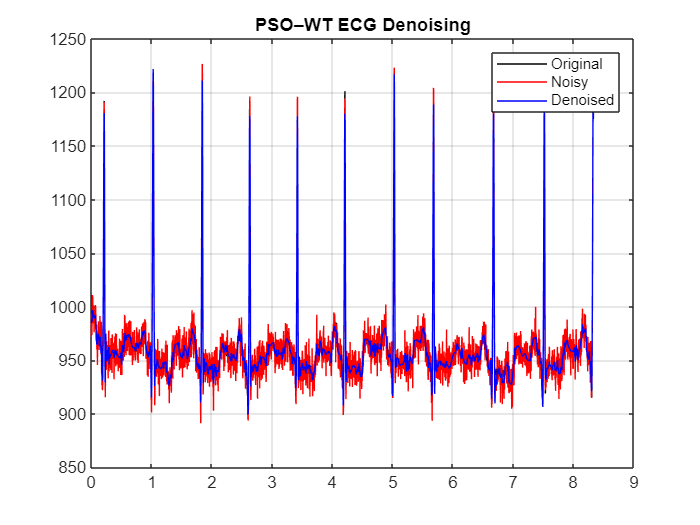

clc;

clear;
close all;
tic
%% Phase I: Initialisation
data = readmatrix('100.csv');
x = data(:,2);
% Original ECG signal S(n)
S = x;          % Use your ECG variable
N = length(S);

fs = 360;
t = (0:N-1)/fs;

figure;
plot(t(1:3000), S(1:3000))
title('Original ECG S(n)')
ylabel('Amplitude')
grid on

# Adding WGN(White Gaussian Noise)

%% Add White Gaussian Noise (Equation 11)

sigma = 0.25 * std(S);
N_noisy = S + sigma * randn(size(S));

figure;
plot(t(1:3000), N_noisy(1:3000))
title('Noisy ECG N(t)')
ylabel('Amplitude')
grid on

%% Calculate SNRinput (Equation 14)
SNR_input = 10*log10(sum(S.^2) / sum((S - N_noisy).^2))

%% Wavelet denoising parameters (Table 1)

Phi_list = {'coif1','coif3','sym3','sym5','db4','db6'};
beta_list = {'s','h'};
lambda_list = {'rigrsure','sqtwolog','heursure','minimaxi'};
rho_list = {'one','sln','mln'};

L_min = 1;
L_max = 10;

%% PSO parameters (Paper)

C1 = 2;
C2 = 2;
NP = 5;        % number of WT parameters
itermax = 2;
pop_size = 50;
w = 0.7;

%% Initialise swarm

for i = 1:pop_size
    
    particle(i).Phi = randi(length(Phi_list));
    particle(i).L = randi([L_min L_max]);
    particle(i).beta = randi(2);
    particle(i).lambda = randi(length(lambda_list));
    particle(i).rho = randi(length(rho_list));
    
    velocity(i).Phi = 0;
    velocity(i).L = 0;
    velocity(i).beta = 0;
    velocity(i).lambda = 0;
    velocity(i).rho = 0;
end

%% SECTION 1: Initial fitness evaluation (Phase II)

for i = 1:pop_size
    
    % Extract parameters from particle
    Phi = Phi_list{particle(i).Phi};
    L = particle(i).L;
    beta = beta_list{particle(i).beta};
    lambda = lambda_list{particle(i).lambda};
    rho = rho_list{particle(i).rho};
    
    % Wavelet denoising (Phase III inside optimisation)
    S_hat = wden(N_noisy, lambda, beta, rho, L, Phi);
    
    % SNRoutput (Equation 15)
    SNR_output = 10*log10(sum(S.^2) / sum((S - S_hat).^2));
    
    % Fitness (Equation 13)
    fitness(i) = SNR_output - SNR_input;
    % Local best
    pbest(i) = particle(i);
    pbest_val(i) = fitness(i);
end

% Global best (Equation 8)
[gbest_val, idx] = max(pbest_val);
gbest = particle(idx);

figure;
plot(1:pop_size, fitness,'bo-','LineWidth',1.5)
xlabel('Particle Index')
ylabel('SNR Improvement (dB)')
title('SNR Improvement for Each Particle')
grid on

%% PSO main loop

for iter = 1:itermax
    
    for i = 1:pop_size
        
        r1 = rand;
        r2 = rand;
        
        % Velocity update (Equation 9)
        velocity(i).L = w*velocity(i).L ...
            + C1*r1*(pbest(i).L - particle(i).L) ...
            + C2*r2*(gbest.L - particle(i).L);
        
        % Position update (Equation 10)
        particle(i).L = round(particle(i).L + velocity(i).L);
        
        % Boundary condition
        particle(i).L = max(L_min, min(L_max, particle(i).L));
        
        % Random re-initialisation for categorical variables
        particle(i).Phi = randi(length(Phi_list));
        particle(i).beta = randi(2);
        particle(i).lambda = randi(length(lambda_list));
        particle(i).rho = randi(length(rho_list));
        
        %% Evaluate again
        
        Phi = Phi_list{particle(i).Phi};
        L = particle(i).L;
        beta = beta_list{particle(i).beta};
        lambda = lambda_list{particle(i).lambda};
        rho = rho_list{particle(i).rho};
        
        S_hat = wden(N_noisy, lambda, beta, rho, L, Phi);
        
        SNR_output = 10*log10(sum(S.^2) / sum((S - S_hat).^2));
        
        fitness(i) = SNR_output - SNR_input;
        
        % Update local best (Equation 7)
        if fitness(i) > pbest_val(i)
            pbest(i) = particle(i);
            pbest_val(i) = fitness(i);
        end
    end
    
    % Update global best
    [gbest_val, idx] = max(pbest_val);
    gbest = pbest(idx);
    
    disp(['Iteration ' num2str(iter) ...
        ' Best SNR improvement = ' num2str(gbest_val)]);
end

%% SECTION 2: Final WT denoising (Phase III)

Phi_opt = Phi_list{gbest.Phi};
L_opt = gbest.L;
beta_opt = beta_list{gbest.beta};
lambda_opt = lambda_list{gbest.lambda};
rho_opt = rho_list{gbest.rho};

S_hat_final = wden(N_noisy, lambda_opt, ...
    beta_opt, rho_opt, L_opt, Phi_opt);

%% Phase IV: Performance measures

% SNRoutput
SNR_output = 10*log10(sum(S.^2) / sum((S - S_hat_final).^2));

% MSE
MSE = mean((S - S_hat_final).^2);

% RMSE
RMSE = sqrt(MSE);

% PRD
PRD = 100 * sqrt(sum((S - S_hat_final).^2) / sum(S.^2));

disp(['Final SNR = ' num2str(SNR_output)]);
disp(['PRD = ' num2str(PRD)]);
disp(['RMSE = ' num2str(RMSE)]);

figure;
plot(t(1:3000), S(1:3000),'k'); hold on
plot(t(1:3000), N_noisy(1:3000),'r');
plot(t(1:3000), S_hat_final(1:3000),'b');
legend('Original','Noisy','Denoised')
title('PSO–WT ECG Denoising')
grid on
